% Experiment 4 - Restnet50 with BoundingBox
% Author: Akshay.R 

close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Read the training, validation and test partitions from the relevant folders

folder = "/Users/akshay/Desktop/ASS/CUB_200_2011_Subset20classes/";
%folder = "P:\CUB_200_2011new\CUB_200_2011\"
trainingImageNames = readtable(fullfile(folder, "train.txt"), ... 
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate.txt", ... 
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test.txt", ... 
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Read bounding box information from bounding_boxes.txt. The format is

boundingBoxes = readtable(folder + "bounding_boxes.txt", ... 
    'ReadVariableNames', false);
boundingBoxes.Properties.VariableNames = {'index', 'x', 'y', 'w', 'h'};

% Map bounding box information to the respective image file name
train_image_box_map = returnMapping(trainingImageNames, boundingBoxes);
val_image_box_map = returnMapping(validationImageNames, boundingBoxes);
test_image_box_map = returnMapping(testImageNames, boundingBoxes);

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, train_image_box_map);
disp('Training set class samples:');

Training set class samples:


countEachLabel(trainingImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, val_image_box_map);
disp('Validation set class samples:');

Validation set class samples:


countEachLabel(validationImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames',   'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, test_image_box_map);
disp('Test set class samples:');

Test set class samples:


countEachLabel(testImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


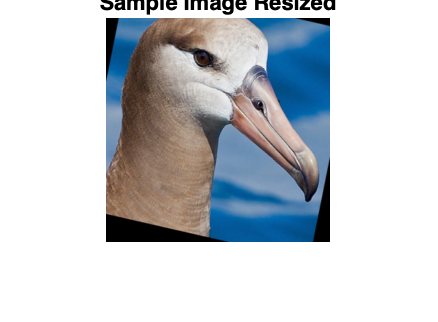


targetSize = [224, 224];

% Data augmentation
augmenter = imageDataAugmenter( ...
    'RandXTranslation',[-20 20], ...
    'RandYTranslation',[-20 20], ...
    'RandRotation',[-20,0], ...
    'RandScale',[0.8,1.2]);
    
augmentedTrainingImageDS = augmentedImageDatastore(targetSize, trainingImageDS, 'DataAugmentation', augmenter, 'OutputSizeMode', 'resize');

% Resize validation and test datastores
validationImageDS_Resized = augmentedImageDatastore(targetSize, validationImageDS, 'OutputSizeMode', 'resize');
testImageDS_Resized = augmentedImageDatastore(targetSize, testImageDS, 'OutputSizeMode', 'resize');

% Display a sample image from the datastore
figure(1);
sampleImageTable = augmentedTrainingImageDS.read();
sampleImageCell = sampleImageTable{1, 1};
sampleImage = sampleImageCell{1};
imshow(sampleImage);
title('Sample Image Resized');

## Display a sample image from the datastore

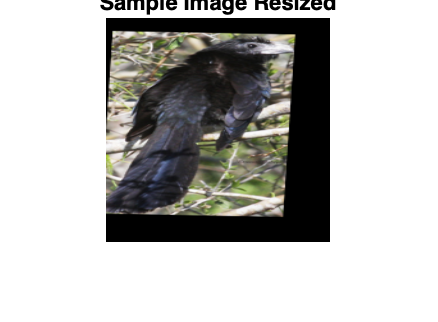

figure(1);
sampleImageTable = augmentedTrainingImageDS.read();
sampleImageCell = sampleImageTable{1, 1};
sampleImage = sampleImageCell{1};
imshow(sampleImage);
title('Sample Image Resized');

## Create a restnet50

net = resnet50;
inputSize = net.Layers(1).InputSize;
lgraph = layerGraph(net);

numClasses = numel(categories(trainingImageDS.Labels));
newFcLayer = fullyConnectedLayer(numClasses, 'Name', 'new_fc');
lgraph = replaceLayer(lgraph, 'fc1000', newFcLayer);

% Find the classification layer's name
classificationLayerName = '';
for i = 1:numel(net.Layers)
    if isa(net.Layers(i), 'nnet.cnn.layer.ClassificationOutputLayer')
        classificationLayerName = net.Layers(i).Name;
        break;
    end
end

newClassLayer = classificationLayer('Name', 'new_classoutput');
lgraph = replaceLayer(lgraph, classificationLayerName, newClassLayer);

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

## Set the training options

options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.001, ...
        'MiniBatchSize', 20, ...
        'MaxEpochs', 5, ...
        'Verbose', true, ...
        'Shuffle', 'every-epoch', ...
        'VerboseFrequency', 1, ...
        'ValidationData', augmentedTrainingImageDS, ...
        'Plots','training-progress');

## Train the simple CNN model

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:34 |       10.00% |        8.41% |       3.3547 |       3.3008 |          0.0010 |
|       1 |           2 |       00:00:37 |        5.00% |              |       3.3874 |              |          0.0010 |
|       1 |           3 |       00:00:40 |        0.00% |              |       3.4304 |              |          0.0010 |
|       1 |           4 |       00:00:43 |       10.00% |              |       3.1782 |   

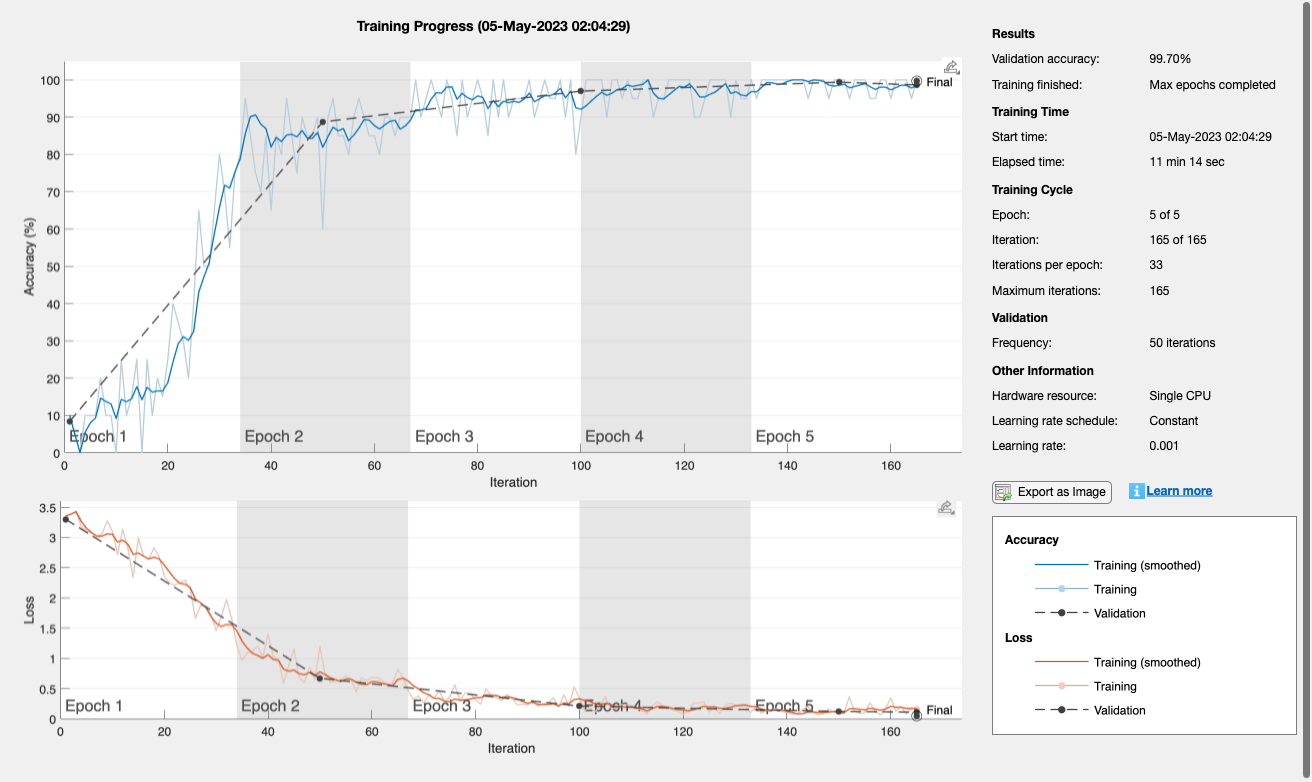

restnet = trainNetwork(augmentedTrainingImageDS, lgraph, options);

## Test the accuracy on the test partition

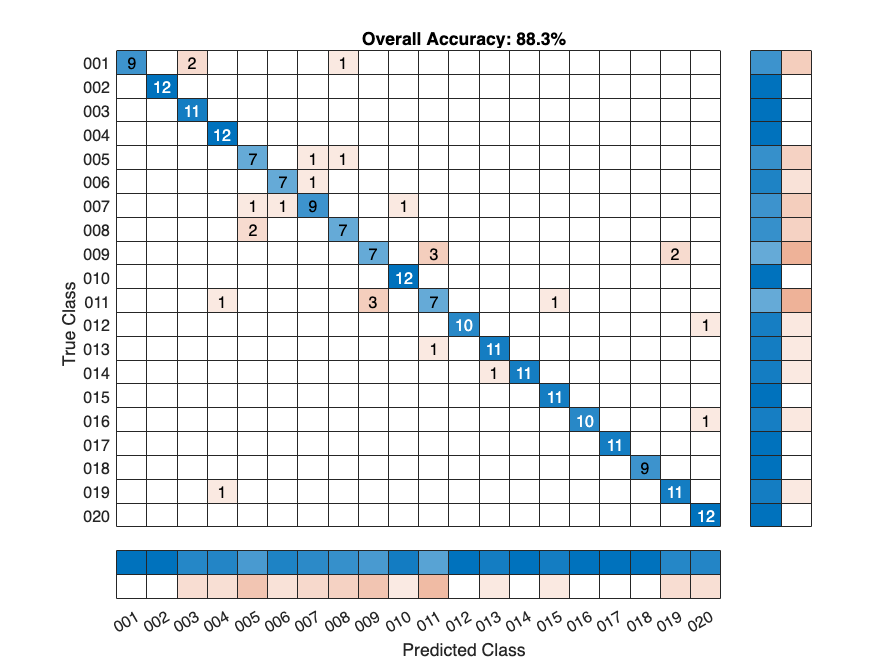

YPred = classify(restnet, testImageDS_Resized);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest); % Output on command line

% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%");

## Compute classwise positive recogniton rate

%% Compute classwise positive recogniton rate
classwisePosRecog = cell(height(order), 2);
samplesPerRow = sum(m, 2);
for iI = 1:height(order)
    classwisePosRecog{iI, 1} = order(iI);  % add image name
    classwisePosRecog{iI, 2} = round(100 * m(iI, iI) / samplesPerRow(iI), 1);  % add recognition rate
end
disp('Classwise Recognition Rates:');

Classwise Recognition Rates:


disp(classwisePosRecog);

    {[001]}    {[     75]}
    {[002]}    {[    100]}
    {[003]}    {[    100]}
    {[004]}    {[    100]}
    {[005]}    {[77.8000]}
    {[006]}    {[87.5000]}
    {[007]}    {[     75]}
    {[008]}    {[77.8000]}
    {[009]}    {[58.3000]}
    {[010]}    {[    100]}
    {[011]}    {[58.3000]}
    {[012]}    {[90.9000]}
    {[013]}    {[91.7000]}
    {[014]}    {[91.7000]}
    {[015]}    {[    100]}
    {[016]}    {[90.9000]}
    {[017]}    {[    100]}
    {[018]}    {[    100]}
    {[019]}    {[91.7000]}
    {[020]}    {[    100]}



disp(classwisePosRecog)

    {[001]}    {[     75]}
    {[002]}    {[    100]}
    {[003]}    {[    100]}
    {[004]}    {[    100]}
    {[005]}    {[77.8000]}
    {[006]}    {[87.5000]}
    {[007]}    {[     75]}
    {[008]}    {[77.8000]}
    {[009]}    {[58.3000]}
    {[010]}    {[    100]}
    {[011]}    {[58.3000]}
    {[012]}    {[90.9000]}
    {[013]}    {[91.7000]}
    {[014]}    {[91.7000]}
    {[015]}    {[    100]}
    {[016]}    {[90.9000]}
    {[017]}    {[    100]}
    {[018]}    {[    100]}
    {[019]}    {[91.7000]}
    {[020]}    {[    100]}



## Helper function for resizing images in transform

function data_out = preprocessData(data, targetSize)
    try
        data_out{1} = imresize(data{1}, targetSize(1:2)); % Resize images
        data_out{2} = data{2};  % Keep labels as they are
    catch e
        % This is solely for debugging
        disp(e) 
    end
end

## Helper function mapping image names to bounding boxes and vice versa

function image_box_map = returnMapping(ImageNames, boundingBoxes)
    image_box_map = containers.Map;
    for i = 1:size(ImageNames, 1) 
        fn = ImageNames{i,2}{1};
        fn = split(fn, "\");
        fn = split(fn, "/");
        image_box_map(fn{end}) = [boundingBoxes{ImageNames{i,1}, 2:5}];
    end
end